Quick interactive tutorial on using Daubechies' wavelets for eigenvalue problems. **[Notebook 2 of 2]**

Solves for eigenvalues of a 1D Quantum Harmonic Oscillator.


$$-\frac{1}{2}\cdot\frac{d^2f(x)}{dx^2} + \frac{x^2}{2} = Ef(x)$$


E = 0.5, 1.5, . . .

[ws,x] = wpfun('db3',1,10); %inspect w, x in the workspace tab!
W = ws(2,:); %mother wavelet
S = ws(1,:); %mother scaling function

Constructing a basis set {S, W}. 

- DT(w, x,  k, n) with k = 1 halves the scale of my wavelets. Ensures their translated copies stay inside [0, 5].

- DT(w, x,  k, n) with n = 0.5, 1.5, ..., 4.5 distributes wavelets evenly around parabolic well centred at 2.5 

basis = [];
for n = (-2:2) + 2.5
    basis = [basis; DT(S,x,1,n)];
end
for n = (-2:2) + 2.5
    basis = [basis; DT(W,x,1,n)];
end

[~, x] = DT(S, x, 1, 0);
sz = size(basis); sz = sz(1);

Visualizing the problem.

- 
$$-\frac{1}{2}\cdot\frac{d^2f(x)}{dx^2} + \frac{(x-2.5)^2}{2} = Ef(x)$$


- 
$$f(x) \equiv s_n^k , w_n^k$$


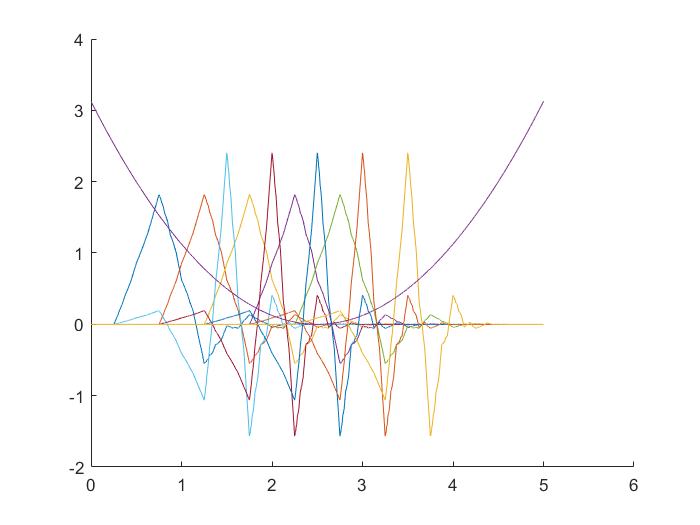

figure(1)
clf 
hold on
for k = 1:sz
plot(x, basis(k,:));
end
plot(x, (x-2.5).^2/2)
hold off

- Everything is zero outside [0, 2K - 1] = [0, 5].

- Wavelets are evenly distributed on either side of the well's centre.

Constructing the Hamiltonian.

- H includes (s,s), (s,w), (w,s), (w,w) overlaps.

- Theres a division by 2^1 because our lowest k = 1

H = zeros([sz sz]); T = zeros([sz sz]); V = zeros([sz sz]);

for i = 1:sz
    for j = i:sz
        T(i, j) = 0.5 * trapz(singlediff(basis(i,:),x) .* singlediff(basis(j,:),x)) * x(2);
        V(i, j) = trapz(basis(i,:) .* ((x-2.5).^2)/2 .* basis(j,:)) * x(2);
    end
end
H = T + V;
H = H + H' - diag(diag(H)); 
H=H/2 

H =     6.0118   -3.3351    0.8641   -0.1131   -0.0053    2.8196   -1.6630    0.1395   -0.0091   -0.0006
   -3.3351    5.6398   -3.3441    0.8665   -0.1132    0.2827    2.8087   -1.6686    0.1398   -0.0091
    0.8641   -3.3441    5.3926   -3.3653    0.8710   -2.9373    0.3204    2.7977   -1.6697    0.1399
   -0.1131    0.8665   -3.3653    5.2706   -3.3805    1.3231   -2.9556    0.3462    2.7866   -1.6731
   -0.0053   -0.1132    0.8710   -3.3805    5.2736    0.0495    1.3239   -2.9897    0.3780    2.7755
    2.8196    0.2827   -2.9373    1.3231    0.0495   36.8545   10.2696   -0.9062    0.1131    0.0053
   -1.6630    2.8087    0.3204   -2.9556    1.3239   10.2696   36.6671   10.2581   -0.9085    0.1132
    0.1395   -1.6686    2.7977    0.3462   -2.9897   -0.9062   10.2581   36.6046   10.3046   -0.9130
   -0.0091    0.1398   -1.6697    2.7866    0.3780    0.1131   -0.9085   10.3046   36.6671   10.3221
   -0.0006   -0.0091    0.1399   -1.6731    2.7755    0.0053    0.1132   -0.9130   10.3

Eigenvalues and eigenfunctions

- Look at MATLAB documentation for *eig*

- It furnishes eigenvectors, eigenvalues in [v, d] for inputted matrix.

[v,d] = eig(H);
clf
fprintf('Numerical: %1.3f\nTheoretical: %1.3f', min(diag(d)), 0.5);
f =(v(:,end)' * basis);

Numerical: 0.515
Theoretical: 0.500

figure(2)
plot(x,f)

- Numerical E = 0.51

- Theoretical E = 0.5

- Peaks of the numerical eigenfunction are consistent with the Gaussian profile expected for this problem.

- 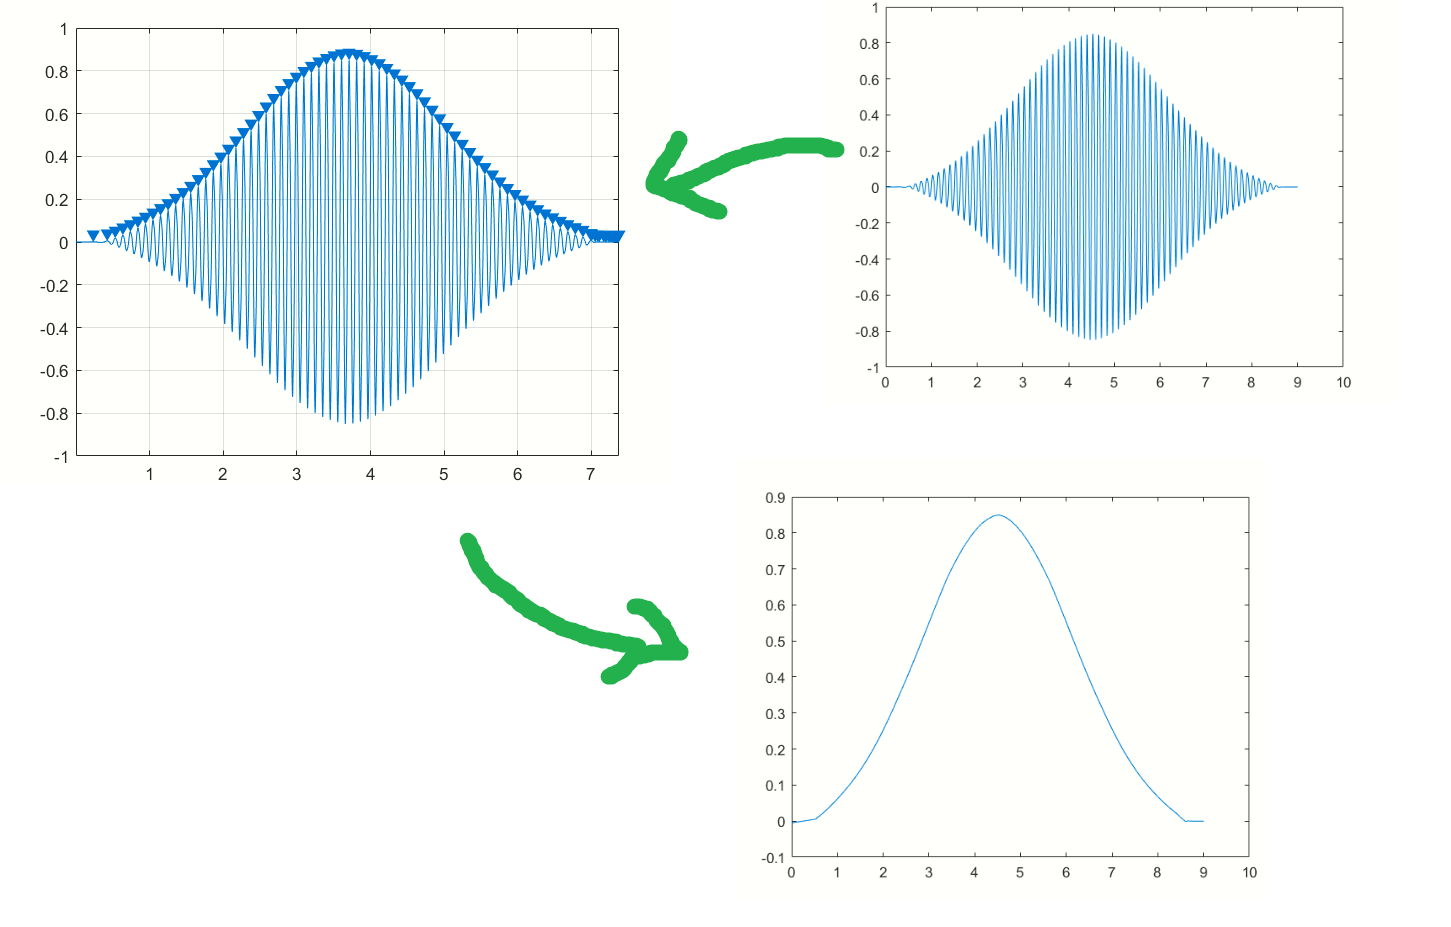

Utility functions to scale, translate, and differentiate. 

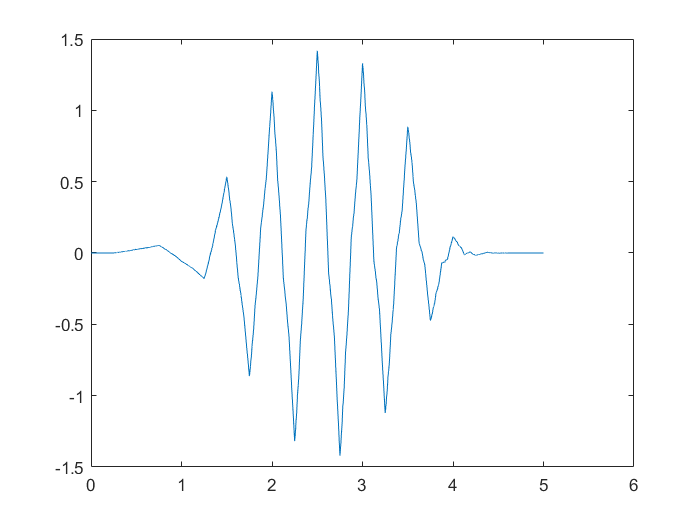

function [DTw, DTx] = DT(w,x,k,n)

    %changes w00 to wkn
    %keep n <= (2K - 1)(2^k - 1)
    DTw = w;
    DTx = x+n;
    
    DTw = 2^(k/2)*DTw;
    DTx = DTx/(2^k);
    
    newxstep = DTx(2) - DTx(1);
    Lpad = round(DTx(1) / newxstep);
    
    DTx = wextend('1', 'asymw', DTx, length(DTx)*(2^k - 1), 'r');
    
    DTw = [DTw , zeros(1,(length(DTx) - length(DTw)))];
    DTw = circshift(DTw, Lpad); DTw(1:Lpad) = zeros(1, Lpad);   
    DTx = wextend('1', 'asymw', DTx, Lpad, 'l');
    
    DTx = DTx(1:length(DTw));
    
end

function [wd, xd] = singlediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    xd = x;
end

function [wdd, xdd] = doublediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    wdd = gradient(wd)/(x(2) - x(1));
    xdd = x;
end

